# Simulation of 2D quantum walk

#### Parameters

clear
clc
close all

InitTime = 0;
FinlTime = 2;
StepTime = 0.03;

%% Lattice geometry

XSize = 25;
YSize = 27;
Center = [500,500];
NumLayer = 3;

AdjNN = [0,1;0,-1;1,0;-1,0;-1,-1;1,1];
Lat = loadCalibration("Lower");

% AdjNN = [0,1;0,-1;1,0;-1,0];
% Lat.V = [0,6;6,0];

Lat.R = Center-round(([XSize,YSize]*Lat.V)/2);
XRange = Center(1)+(-80:80);
YRange = Center(2)+(-80:80);

#### Simulation

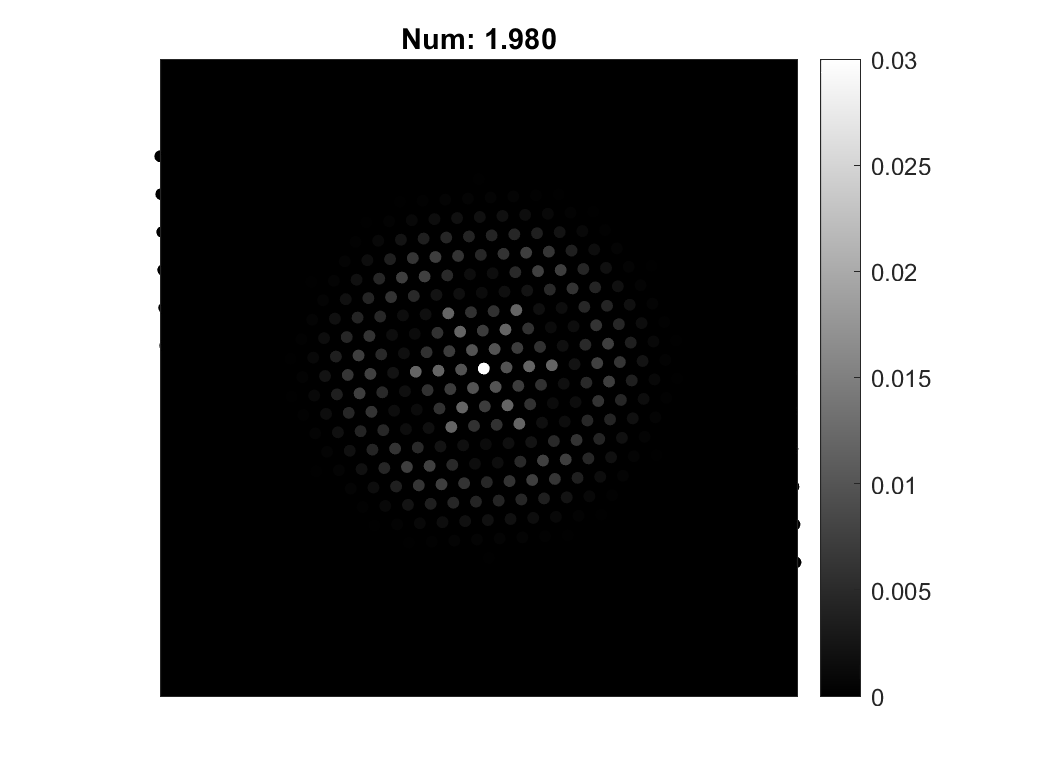

LatFormat = {'Rectangular',1:XSize,1:YSize};
[Site,NumSite] = prepareSite(LatFormat);
InitSite = round(NumSite/2);

Hamitonian = zeros(NumSite,NumSite);
for i = 1:NumSite
    Center = Site(i,:);
    NNX = Center(1)+AdjNN(:,1);
    NNY = Center(2)+AdjNN(:,2);
    NNIndex = NNX>0 & NNX<=XSize & NNY>0 & NNY<=YSize;
    NNXY = NNX(NNIndex)+(NNY(NNIndex)-1)*XSize;
    Hamitonian(i,NNXY) = 1;
end

InitState = zeros(NumSite,1);
InitState(InitSite) = 1;

Time = InitTime:StepTime:FinlTime;
NumStep = length(Time);
State = zeros(NumSite,NumStep);
State(:,1) = InitState;
Evolution = expm(1i*Hamitonian*StepTime);

figure
imagesc(YRange,XRange,zeros(length(XRange),length(YRange)))
daspect([1 1 1])
checkCalibration(Lat,Site,20,InitState,'filled')
caxis([0 0.03])
colorbar
colormap gray
title('Num: 0.000')
H = gca().Children(1);
xticks([])
yticks([])

MeanLayer = zeros(NumStep,NumLayer+1);
SumLayer = zeros(NumStep,NumLayer+1);
MeanLayer(1,1) = 1;
SumLayer(1,1) = 1;
LayerSite = cell(1,NumLayer+1);
for i = 1:NumLayer+1
     [~,~,Outer] = generateAdj(AdjNN,i-1,1);
    LayerSite{i} = InitSite+Outer(:,1)+Outer(:,2)*XSize;
end

for i = 2:NumStep
    State(:,i) = Evolution*State(:,i-1);
    H.CData = abs(State(:,i)).^2;
    title(sprintf('Num: %.3f',Time(i)))
    drawnow
    
    for j = 1:NumLayer+1
        SumLayer(i,j) = sum(abs(State(LayerSite{j},i)).^2);
        MeanLayer(i,j) = mean(abs(State(LayerSite{j},i)).^2);
    end
end

#### **Plot layer statistics**

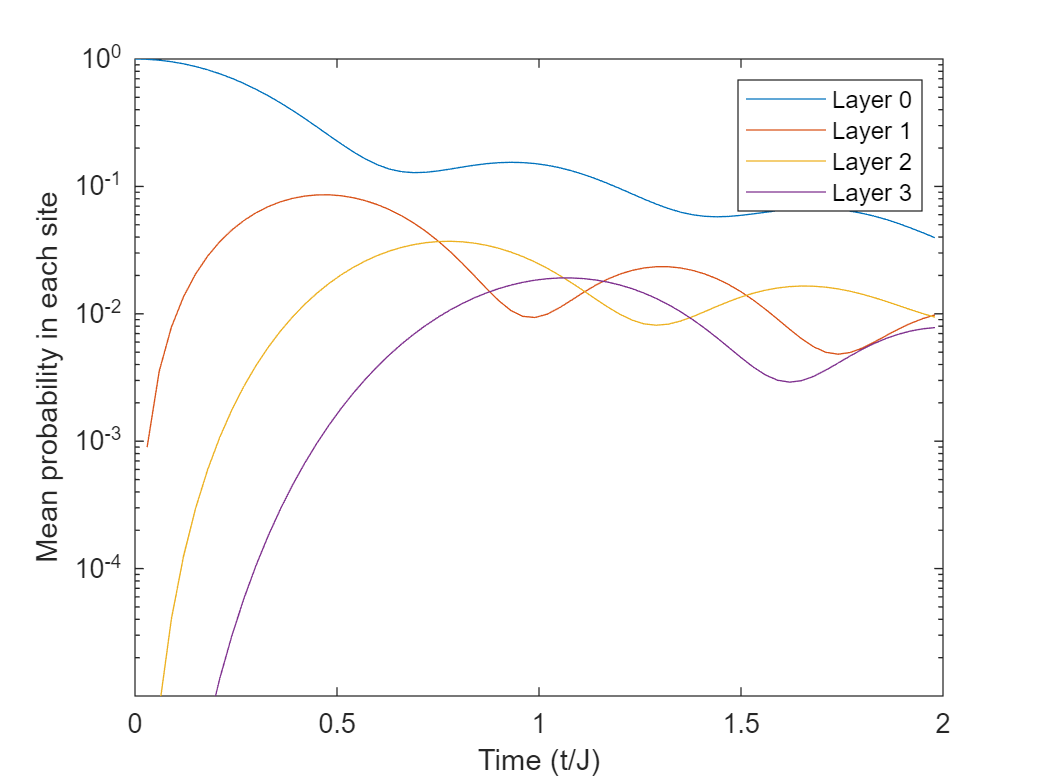

figure
semilogy(Time,MeanLayer)
xlabel('Time (t/J)')
ylabel('Mean probability in each site')
ylim([1e-5,1])
legend({'Layer 0','Layer 1','Layer 2','Layer 3'})

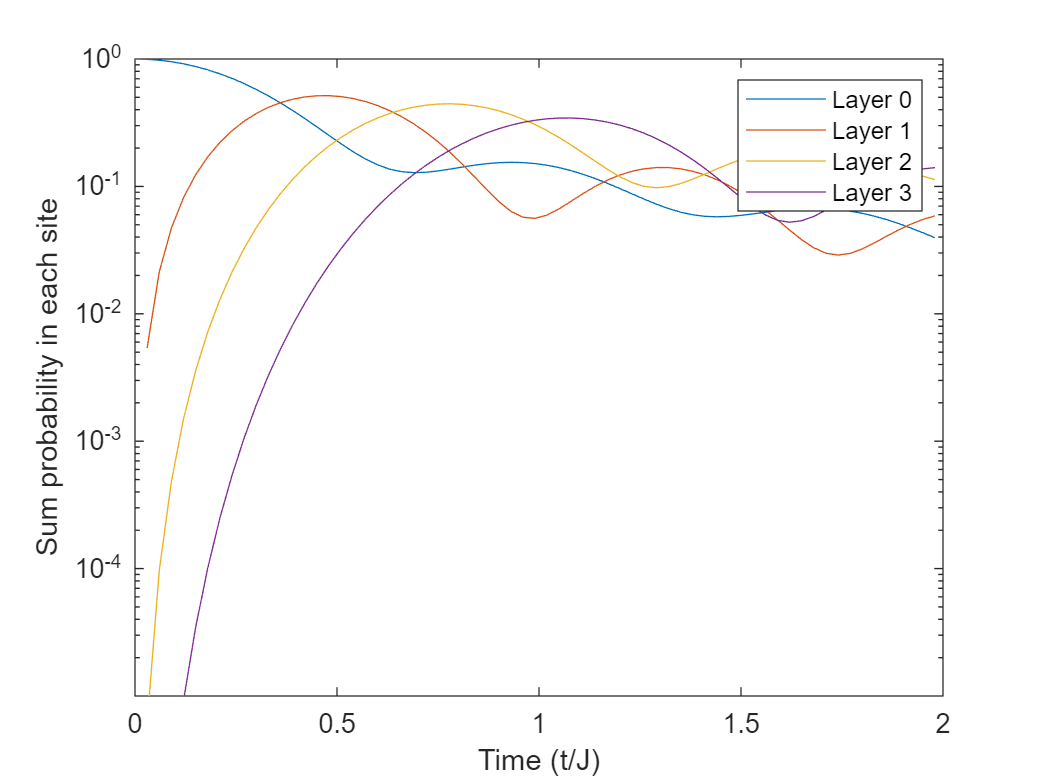

semilogy(Time,SumLayer)
xlabel('Time (t/J)')
ylabel('Sum probability in each site')
ylim([1e-5,1])
legend({'Layer 0','Layer 1','Layer 2','Layer 3'})